Generating a dataset containing 4 clusters each witch 100 points

Each point has x and y coordinates

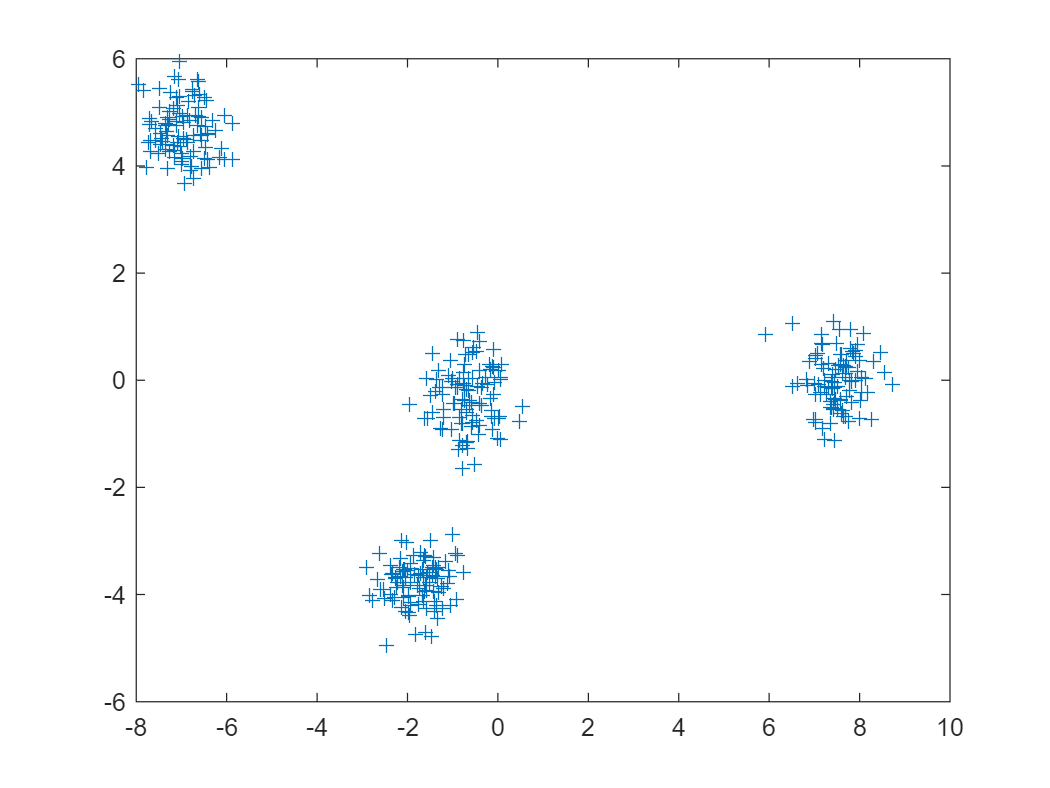

clear
close all
x=[-10 10; -5 5];
V = nngenc(x, 4, 100, 0.5);
plot(V(1,:), V(2,:), '+');

We label the points creating a dataset with 600 observations, each having 2 features and a label form 1 to 4

l=length(V);
i=1;
while i<=l
V(3,i)=1;
V(4,i+1)=1;
V(5,i+2)=1;
V(6,i+3)=1;
i=i+4;
end

We split the dataset into a training and testing set


TR_number = ceil(length(V)*0.9);
VA_number = ceil(length(V)*0);
TE_number = ceil(length(V)*0.1);

TR_Vs = V(3:6,1:TR_number);
VA_Vs = V(3:6,TR_number+1:TR_number+VA_number);
TE_Vs = V(3:6,TR_number+VA_number+1:end);
TR_Vu = V(1:2,1:TR_number);
VA_Vu = V(1:2,TR_number+1:TR_number+VA_number);
TE_Vu = V(1:2,TR_number+VA_number+1:end);



save TR_Vu TR_Vu
save VA_Vu VA_Vu
save TE_Vu TE_Vu
save TR_Vs TR_Vs
save VA_Vs VA_Vs
save TE_Vs TE_Vs
save V

After training a 3 layer NN using nnstart on the training set we display the labes from NN from teseting set.

We observe taht each 4 colums we repeate 1 2 3 4 wchich we want to see. This NN has a 100% acuracy on both the training and the testing set.

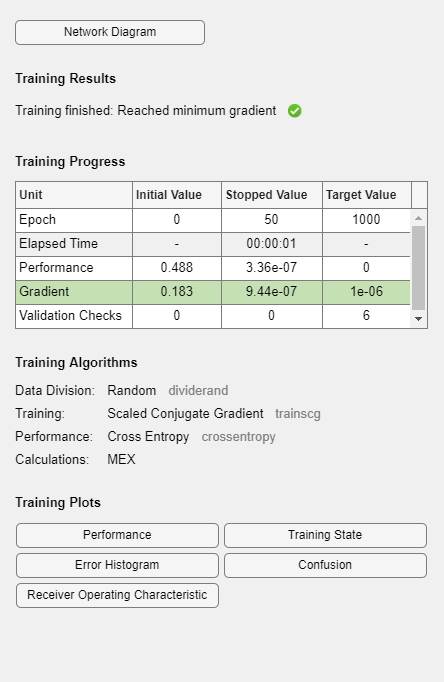

x = TR_Vu;
t = TR_Vs;
trainFcn = 'trainscg';
hiddenLayerSize = 3;
net = patternnet(hiddenLayerSize, trainFcn);
net.divideParam.trainRatio = 90/100;
net.divideParam.valRatio = 5/100;
net.divideParam.testRatio = 5/100;
[net,tr] = train(net,x,t);

genFunction(net,'myNeuralNetworkFunctionjeden','MatrixOnly','yes');

 
MATLAB function generated: myNeuralNetworkFunctionjeden.m
To view generated function code: edit myNeuralNetworkFunctionjeden
For examples of using function: help myNeuralNetworkFunctionjeden
 


disp(myNeuralNetworkFunctionjeden(TE_Vu));

  Columns 1 through 8

    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000
    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000

  Columns 9 through 16

    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000
    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000

  Columns 17 through 24

    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000
    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000
    0.0000    0.0000    0.0000    1

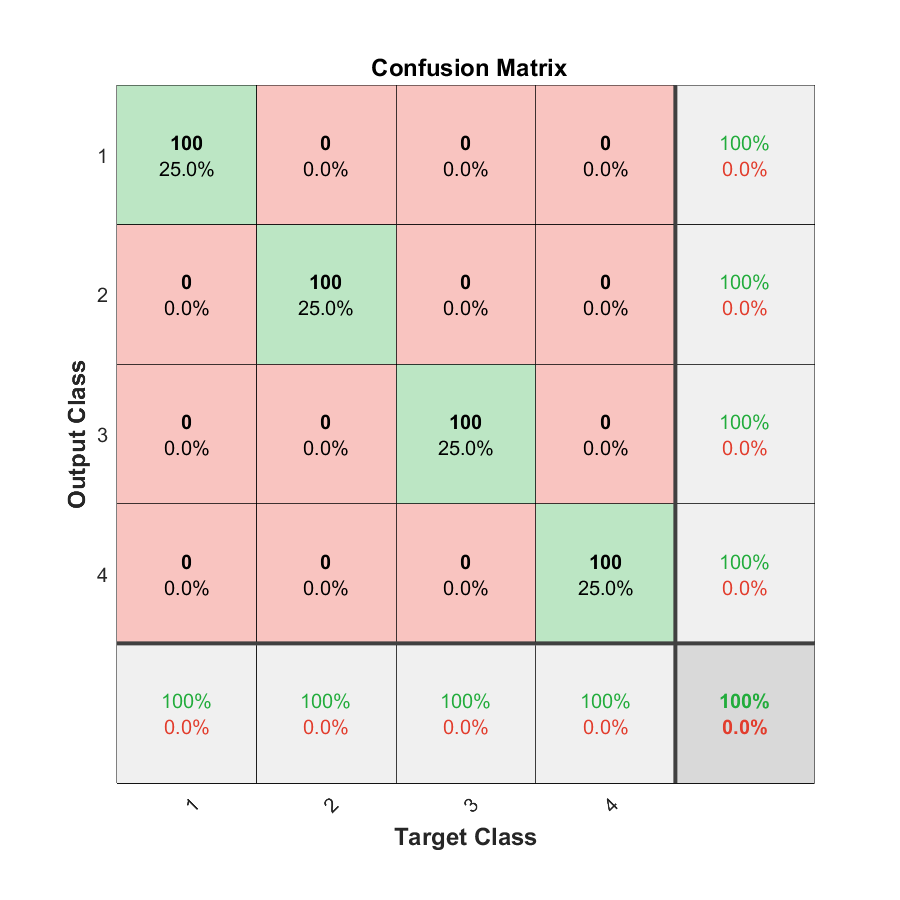

plotconfusion(V(3:6,:),myNeuralNetworkFunctionjeden(V(1:2,:)))

clear;
close all
clear T
clear i
clear n
x1=load('x.mat')

x1 = struct with fields:
      T: [2×361 double]
      i: 10
      m: 10
      n: 10
    out: [1×1 Simulink.SimulationOutput]
      r: 362
      t: [0 0.2500 0.5000 0.7500 1 1.2500 1.5000 1.7500 2 2.2500 2.5000 2.7500 3 3.2500 3.5000 3.7500 4 4.2500 4.5000 4.7500 5 5.2500 5.5000 5.7500 6 6.2500 6.5000 6.7500 7 7.2500 7.5000 7.7500 8 8.2500 8.5000 8.7500 9 9.2500 9.5000 9.7500 10 10.2500 … ]
      x: [344×361 double]


r=1;
m=10;
for i=1:0.25:10
    for n=1:0.25:10

T(r,:)=[i;n];
r=r+1;
    end
end

T=T';
out=sim("smoczek.slx");
t=(out.simout.Time)';
x=(out.simout.Data);

The length of T determines the number of training examples we'll heve, and the nr of rows in the x vector determines the number of outputs the NN hes to produce. From testing (in short) the higher the length of t, the deeper the network and the lower the nr of rows of x the greter the accuracy of NN

In the plot below we see the inaccuracy of the function form simulation given the low(51) nr of x positions

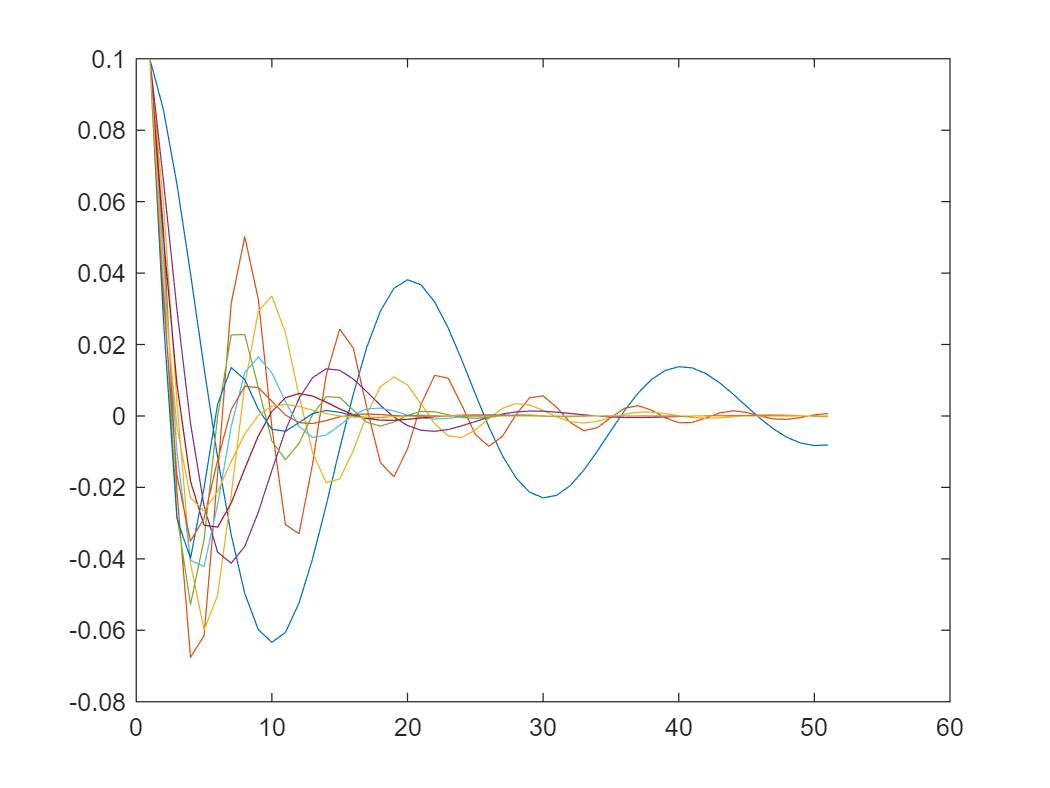

plot(x(:,1:100:1000));

In the plot below (in blue) we see good resolution from the simulation for 344 x positions but a very poor aproximation from the NN

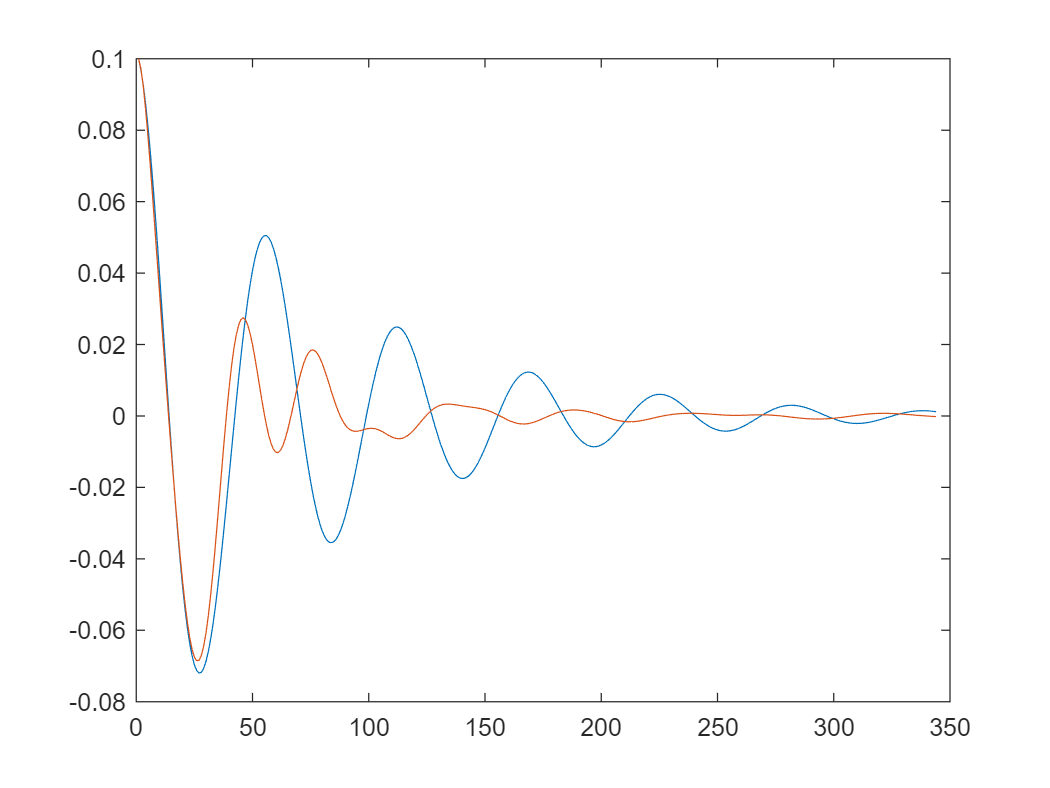


plot(x1.x(:,3));hold on;
plot(myNeuralNetworkFunction2(x1.T(:,3)));hold off;

Below is the plot of a 10 layer NN trained using a 100 examples. We see very poor results. 

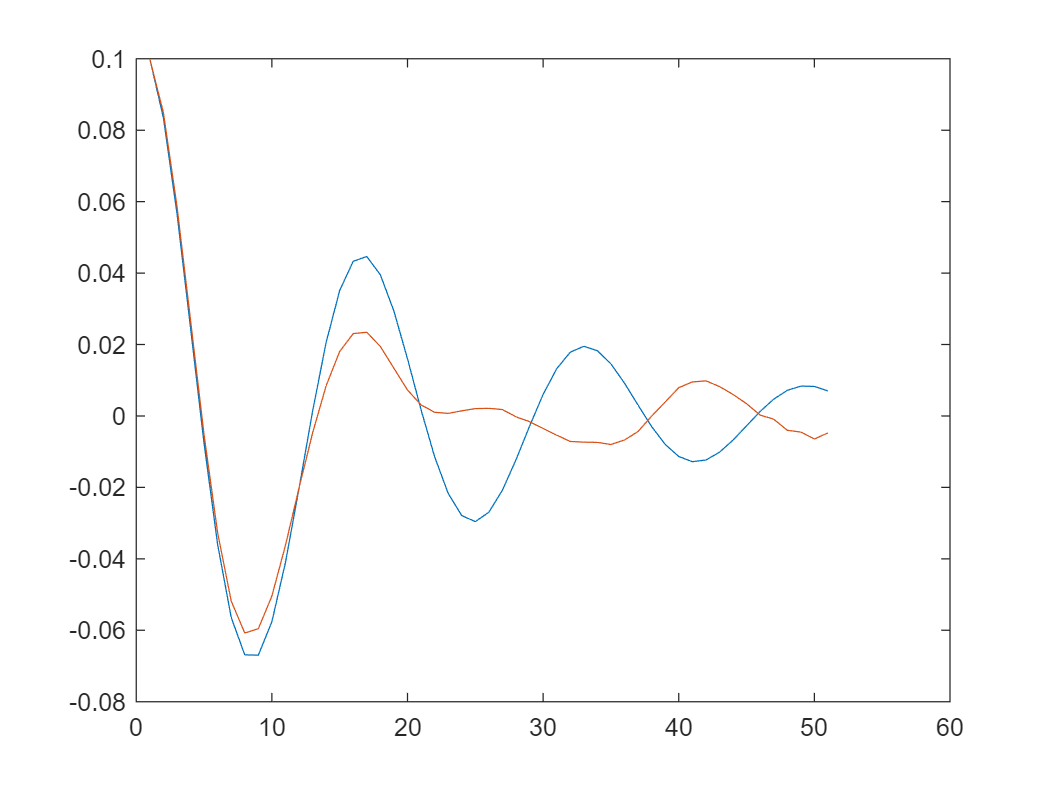

plot(x(:,3));hold on;
plot(myNeuralNetworkFunction3(T(:,3)));hold off;

Below i trained the same nawtork with the same parameters as before. Despite the parameters being the same we see hardly better results but defineatly different results prooving that that training NN is non deterministic (same process yelds different results)

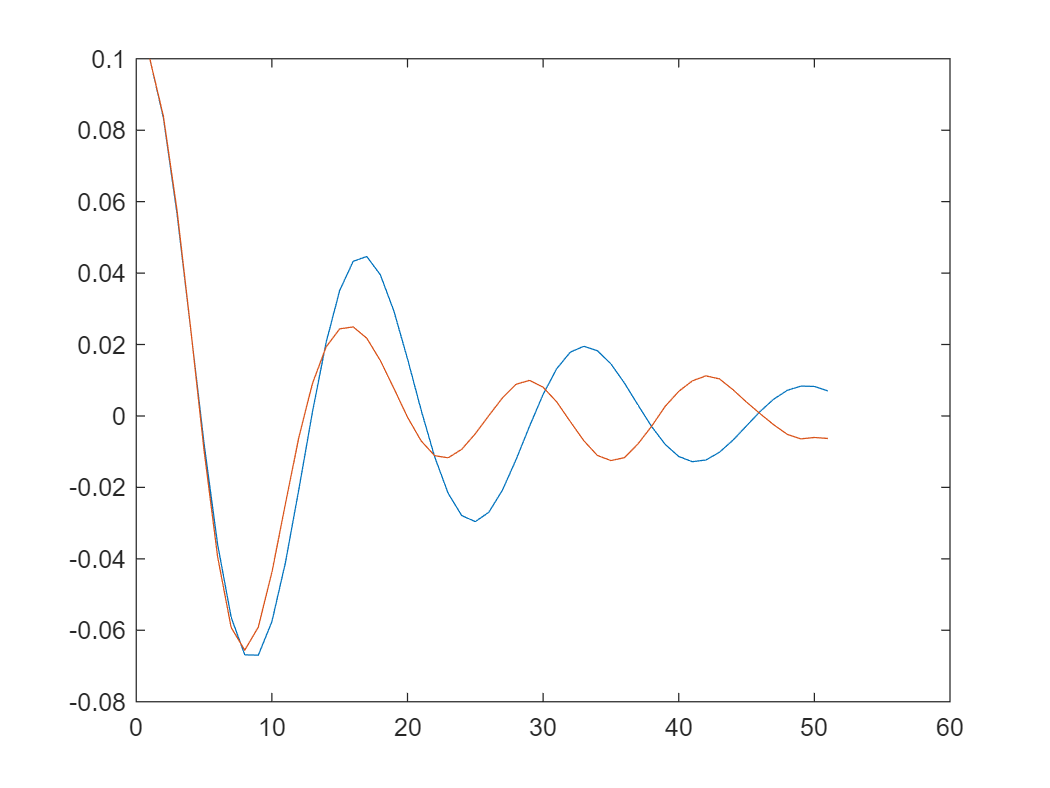

plot(x(:,3));hold on;
plot(myNeuralNetworkFunction4(T(:,3)));hold off;

Below is the plot of a 30 layer NN trained using a 100 examples. The results see no meaningful improovements.

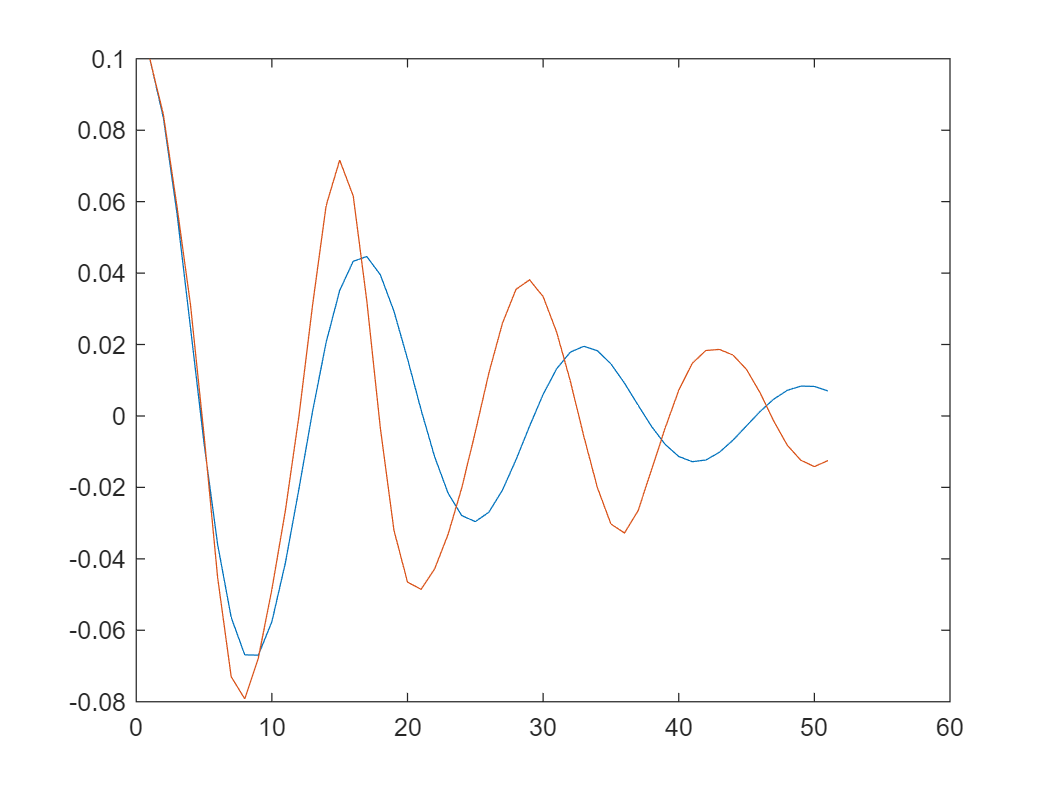

plot(x(:,3));hold on;
plot(myNeuralNetworkFunction5(T(:,3)));hold off;

Below is the plot of a 30 layer NN trained using a 361 examples. Similar error as before.

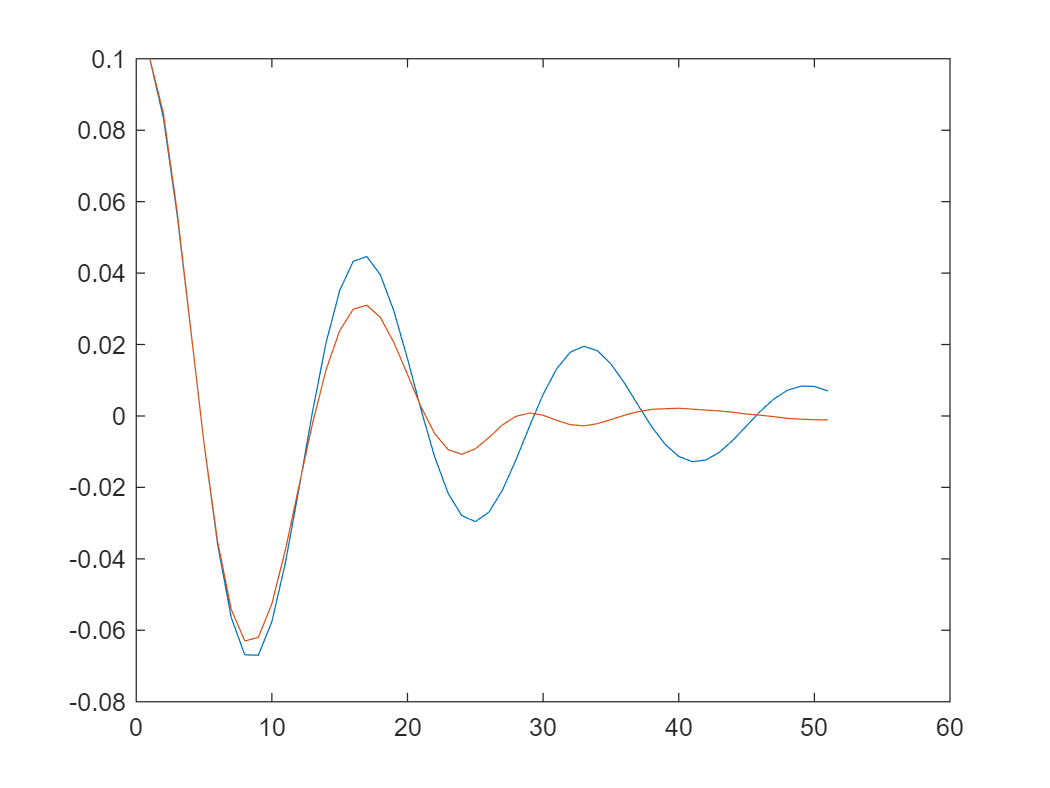

plot(x(:,3));hold on;
plot(myNeuralNetworkFunction6(T(:,3)));hold off;

Below is the plot of a 35 layer NN trained using a 1369 examples. We see very good results compared to previous NN

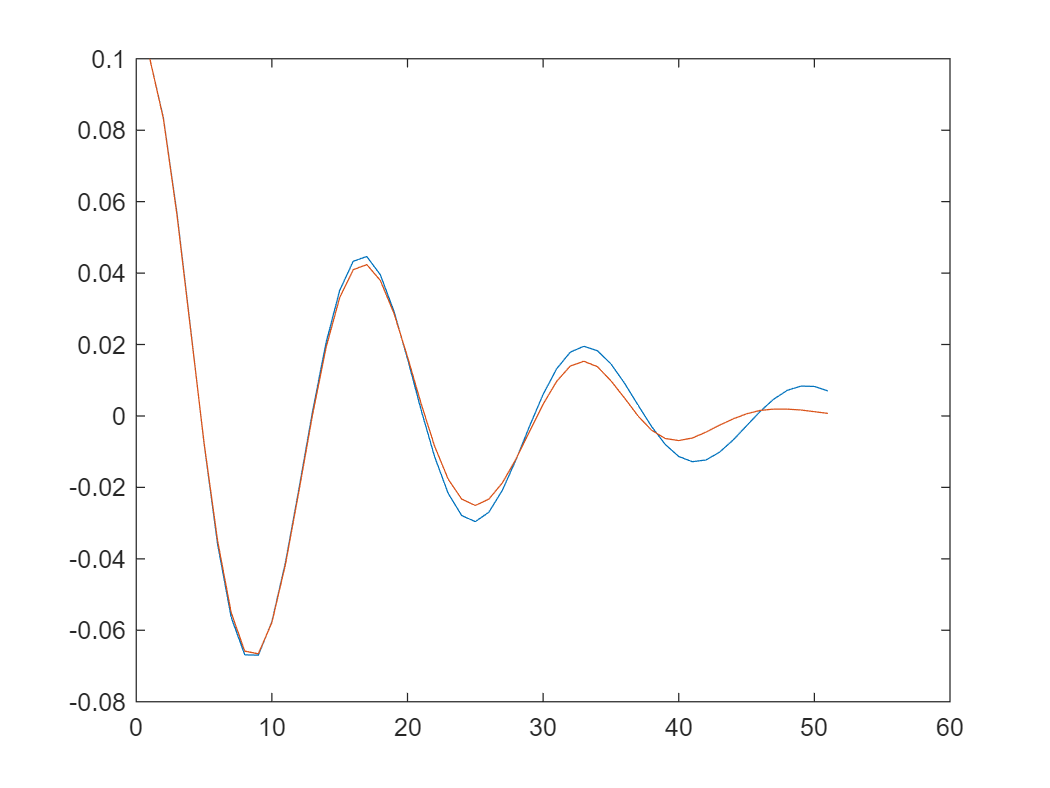

plot(x(:,3));hold on;
plot(myNeuralNetworkFunction8(T(:,3)));hold off;

We observe that although close the NN cannot exactly reproduce values from the simulation. Given the fact that on my intel i3-8100 the simulation took 1 sec and the training took 30min the amount on computing needed makes NN a very bad solution for solving differential equations.

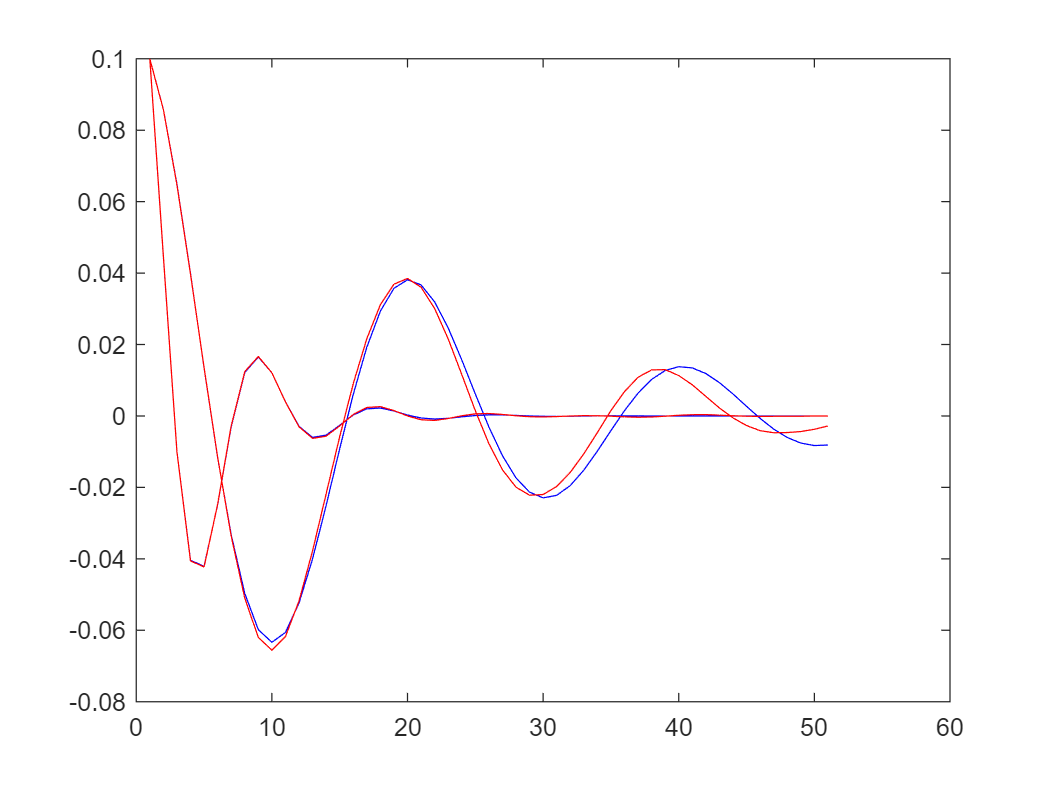

plot(x(:,1:500:1000),'b');;hold on;
plot(myNeuralNetworkFunction8(T(:,1:500:1000)),'r');hold off;